# Sistema de dos masas y tres resortes 

## Con fricción

Ley de Hooke: 

 $F=-k\;x$                (fuerza de restauración)

Fuerza de fricción entre las masas y la superficie:

$F=-b\;x^{\prime \;} =-b\;v$   (amortiguamiento)

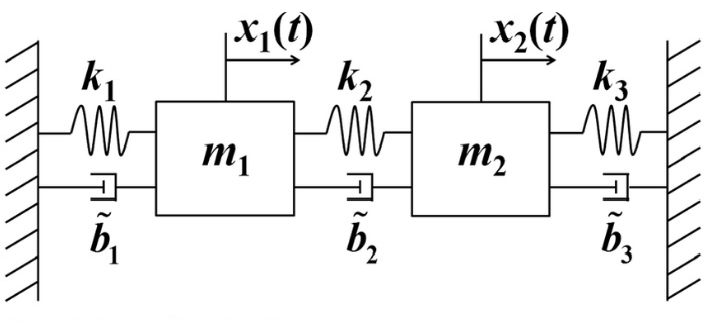

The equation describing the position x of an unforced mass-spring system with damping is a second-order equation.

System of two linear second order homogeneous ODE:


$$m_1 \;x_1^{\textrm{''}} =-k_1 x_1 -k_2 \left(x_1 -x_2 \right)-bx_1^{\prime }$$



$$m_2 \;x_2^{\textrm{''}} =-k_2 \left(x_2 -x_1 \right)-k_3 x_2 -bx_2^{\prime } \;$$



$$x_1^{\textrm{''}} =\frac{-\left(k_1 +k_2 \right)}{m_1 }x_1 +\frac{k_2 }{m_1 }x_2 -\frac{b}{m_1 }\;x_1^{\prime }$$



$$x_2^{\textrm{''}} =\frac{k_2 }{m_2 }x_1 +\frac{-\left(k_2 +k_3 \right)}{m_2 }x_2 -\frac{b}{m_2 }\;x_2^{\prime }$$
 


$$x=\left\lbrack x_1 ;x_2 \right\rbrack$$



$$x^{\textrm{''}\;} =\left\lbrack \begin{array}{cc}
\frac{-\left(k_1 +k_2 \right)}{m_1 } & \frac{k_2 }{m_1 }\\
\frac{k_2 }{m_2 } & \frac{-\left(k_2 +k_3 \right)}{m_2 }
\end{array}\right\rbrack x-\left\lbrack \begin{array}{cc}
\frac{b}{m_1 } & 0\\
0 & \frac{b}{m_2 }
\end{array}\right\rbrack x^{\prime } =\textrm{Mx}-M_{b\;} x^{\prime }$$


Rewrite as a system of four linear first order ODE (Cauchy form):


$$x_1^{\prime } =v_1$$



$$x_2^{\prime } =v_2$$



$$v_1^{\prime } =\frac{-\left(k_1 +k_2 \right)}{m_1 }x_1 +\frac{k_2 }{m_1 }x_2 -\frac{b}{m_1 }\;v_1$$



$$v_2^{\prime } =\frac{k_2 }{m_2 }x_1 +\frac{-\left(k_2 +k_3 \right)}{m_2 }x_2 -\frac{b}{m_2 }\;v_2$$



$$v=\left\lbrack v_1 ;v_2 \right\rbrack$$



$$x^{\prime } =v$$



$$v^{\prime } =\textrm{Mx}-M_{b\;} v$$


 
$$\textrm{xv}=\left\lbrack x;v\right\rbrack$$


${\left(\textrm{xv}\right)}^{\prime } =\left\lbrack \begin{array}{cc}
0 & I\\
M & {-M}_b 
\end{array}\right\rbrack \textrm{xv}=M_d \;\textrm{xv}$    ( ${\left(\textrm{xv}\right)}^{\prime } =f\left(\textrm{xv}\right)$ ; $f$ no depende de $t$ explícitamente )

m = 0.05*ones(2,1);       % masas [kg]
k = 0.01*ones(3,1);       % constantes de los resortes
b = 0.0125;               % friction constant [N/(m/s)]
% b = 0; % prueba sin fricción

M = [-(k(1)+k(2))/m(1), k(2)/m(1);
    k(2)/m(2), -(k(2)+k(3))/m(2)];
Mb = diag(b./m);
Md = [zeros(2,2), eye(2); M, -Mb];

f = @(t,xv) Md*xv;

TS = 40;        % Tiempo que dura la simulación ([s])
np = 100;       % Número de pasos
h = TS/np;      % Tamaño del paso 

ivps = 'rk4';  % probar con 'Euler' 

% condiciones iniciales x1=x2 o x1=-x2
x0 = 0.025;
xv0 = [x0;-x0;0;0];

tspan = [0, TS];
[t,xv] = ivpsV(f, xv0, tspan, h, ivps);

figure
plot(t,xv(1,:));
hold on;
plot(t,xv(2,:));
grid on;
title('Positions')
legend('x1','x2')
xlabel('t [s]')
ylabel('x [m]')

Solutions to differential equations can be represented as summations of periodic contributions bounded by exponential amplitudes.

The eigenvalues represent the powers of these exponential functions:

- When an exponential has a positive power (positive eigenvalue), then its contribution does not decay to a fixed point; instead the contribution grows - this is the 'unstable' eigenvalue.

- With a negative power (negative eigenvalue), the contribution decays to a fixed value - ie. stable eigenvalue.

The eigenvalues of $M_d$ give information about the speed of response and the oscillation frequency, if any.

lambda = eig(Md)                % 4 valores propios (2 complejos conjugados)

Oscillation frequency

w = imag(lambda);               % motion angular frequency ([radianes/s])
T = (2*pi)./w                   % two modes of oscillation, period [s]

Decay rate (of the exponential)

p = real(lambda(1))             % p es negativo (el mismo para los cuatro valores)
x = xv(1:2,:);
Xmax = max(max(abs(x)));
plot(t,Xmax*exp(p*t))
plot(t,-Xmax*exp(p*t))
legend('x1', 'x2', 'envolvente -', 'envolvente +')
hold off;
grid on

Four times the dominant time constant gives the time it takes for the free response to become aproximately zero.

tau = -1./p;     % time constant
dtc = 4*max(tau)

## Energías cinética y potencial

x = xv(1:2,:);
v = xv(3:4,:);
ke = 0.5*m'*(v.^2);
deltaL = [x(1,:);x(1,:)-x(2,:);x(2,:)]; 
pe = 0.5*k'*(deltaL.^2);

E = ke + pe; 
plot(t,E,'r') 
hold on 
plot(t,ke,'g') 
plot(t,pe,'b') 
title('Energy') 
legend('total', 'kinetic', 'potential');
xlabel('t [s]')
ylabel('E [J]')
max(E) - min(E)

## Solución analítica

syms x1(t) x2(t) 
x = [x1;x2];
eqnM = diff(x,t,2) + Mb*diff(x,t,1) - M*x == 0;
[x1G, x2G] = dsolve(eqnM);  

Dx = diff(x,t);
% solución particular - depende de V, D,  x(0) y v(0)
x0 = 0.025;
cond = [x(0) == [x0;-x0], Dx(0) == [0;0]];
[x1P, x2P] = dsolve(eqnM, cond) 
T = (2*pi)/(sqrt(935)/40)
cond = [x(0) == [x0;x0], Dx(0) == [0;0]];
[x1P, x2P] = dsolve(eqnM, cond) 
T = (2*pi)/(sqrt(295)/40)

Insufficient number of outputs from right hand side of equal sign to satisfy assignment.